# EE 521 Power System Analysis and EE 523 Power System Stability and Control Algorithms

### Preamble and Control Inputs

tic;
addpath functions\
systemName = "ieee14"

systemName = "ieee14"

powerFlowMethod =  "NRPF" 

powerFlowMethod = "NRPF"

doContinuationPowerFlow = true;
displayCPFResults = true;
plotCPFPlots = true;
CPF_Bus = 10

CPF_Bus = 10

useSparseDSA = false;
includeOPFScenarios = false;
showOPFFormulae = false;
showOPFValues = false;
numIterations = 50; %I don't wait for the system to converge, 
printPowerFlowConvergenceMessages = false;
% neither do I care if the system converges earlier.
toleranceLimit = 1e-3; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayRawData = true;
displayYBus = false;
displayTables = true; %show busData, branchData, ybus, 
% basically data structures which are not the final output.
printJacobians = false  ; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = false; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
showPlots = true;
displayResults = true;
reducedBranchColumnsCDFReading = true; 
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system
folder_processedData = "processedData/";
% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranch] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);
if displayTables && displayRawData
    displayRawDataAsTables(busData, branchData, N, numBranch);
end

busData = 14×18 table
    bus       busName        loadFlowArea    lossZone    busType    vFinal    deltaFinal     PL      QL      PG       QG      kVBase    Vset     Qmax    Qmin    G     B      remoteControlledBusNumber
    ___    ______________    ____________    ________    _______    ______    __________    ____    ____    _____    _____    ______    _____    ____    ____    _    ____    _

branchData = 20×15 table
    i    j     loadFlowArea    lossZone    ckt    type       R          X         B       MVA1    MVA2    MVA3    controlBusNumber    side      a  
    _    __    ____________    ________    ___    ____    _______    _______    ______    ____    ____    ____    ________________    ____    _____

    1     2         1             1         1      0      0.01938    0.05917    0.0528     0       0       0             0             0          0
    1     5         

N = 14

numBranch = 20

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table.`

if useSparseDSA && ~doContinuationPowerFlow && ~includeOPFScenarios
    [nnzYBus, NYBus] = makeSparseYBus(busData, branchData, displayTables, displayYBus);
else
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);
    ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)]);

end

if ~useSparseDSA && displayTables && displayYBus
    display(ybusTable);
end

### Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

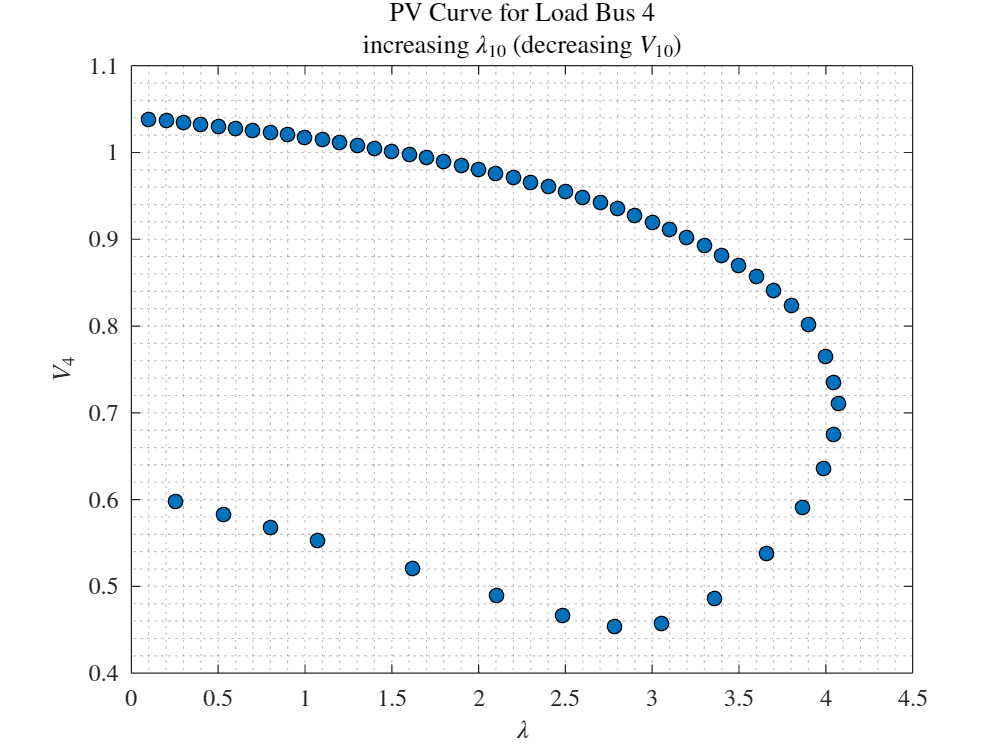

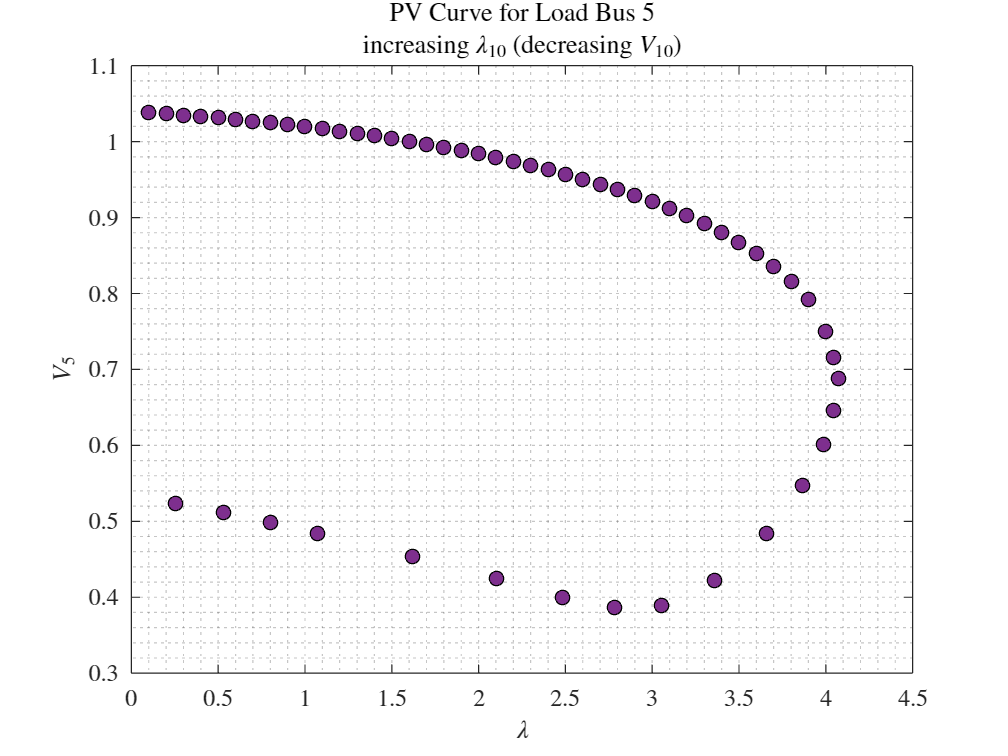

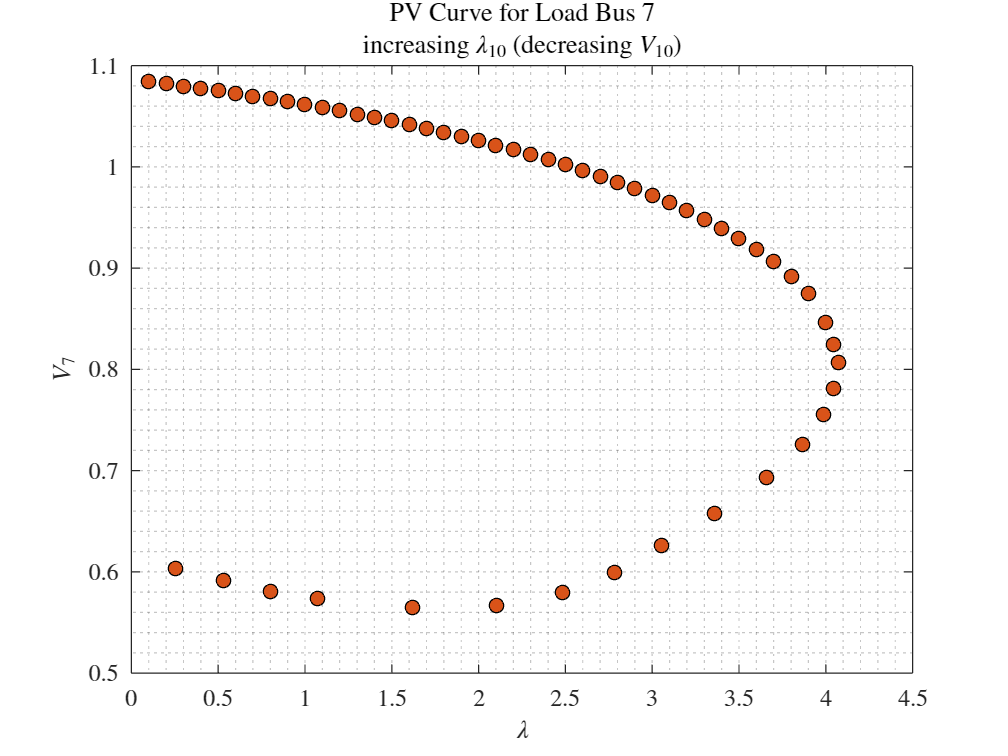

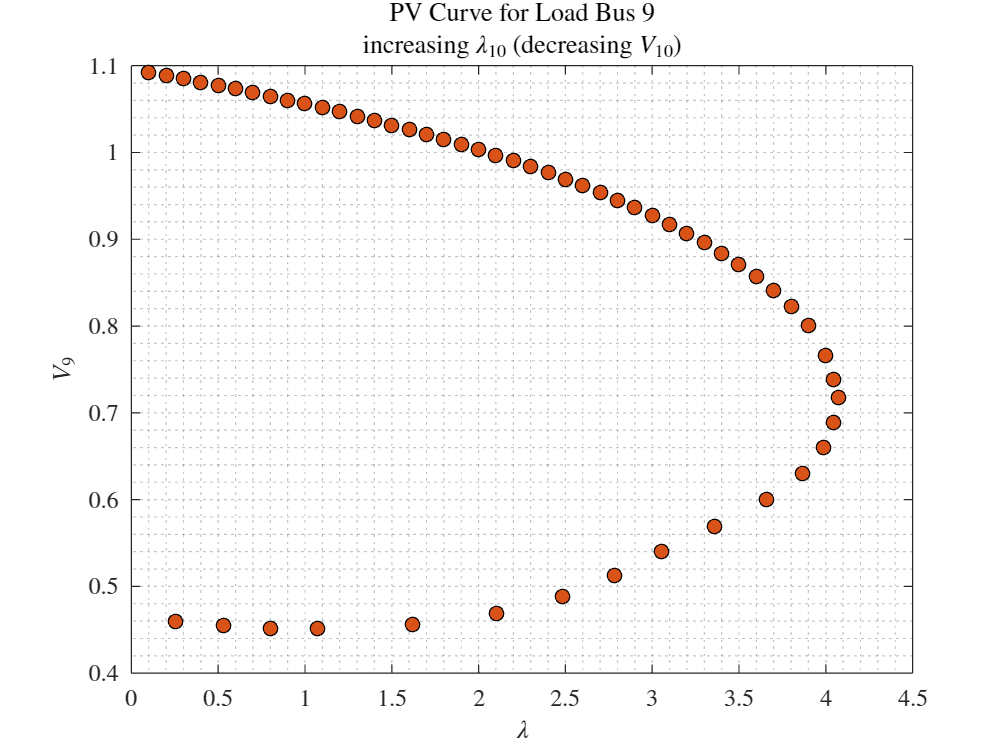

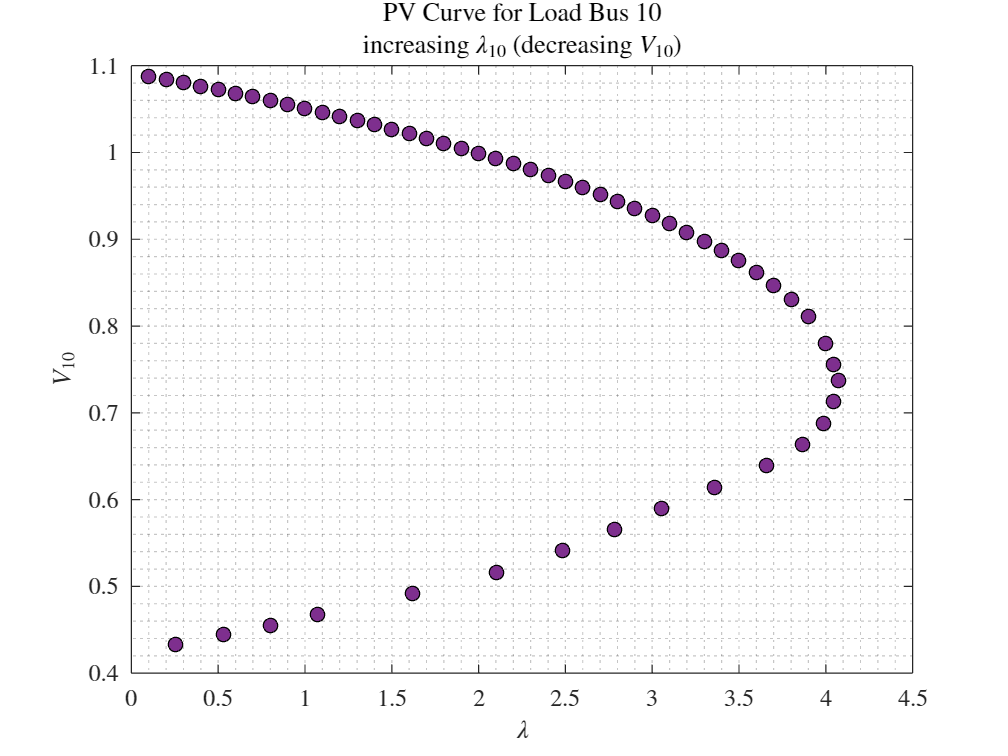

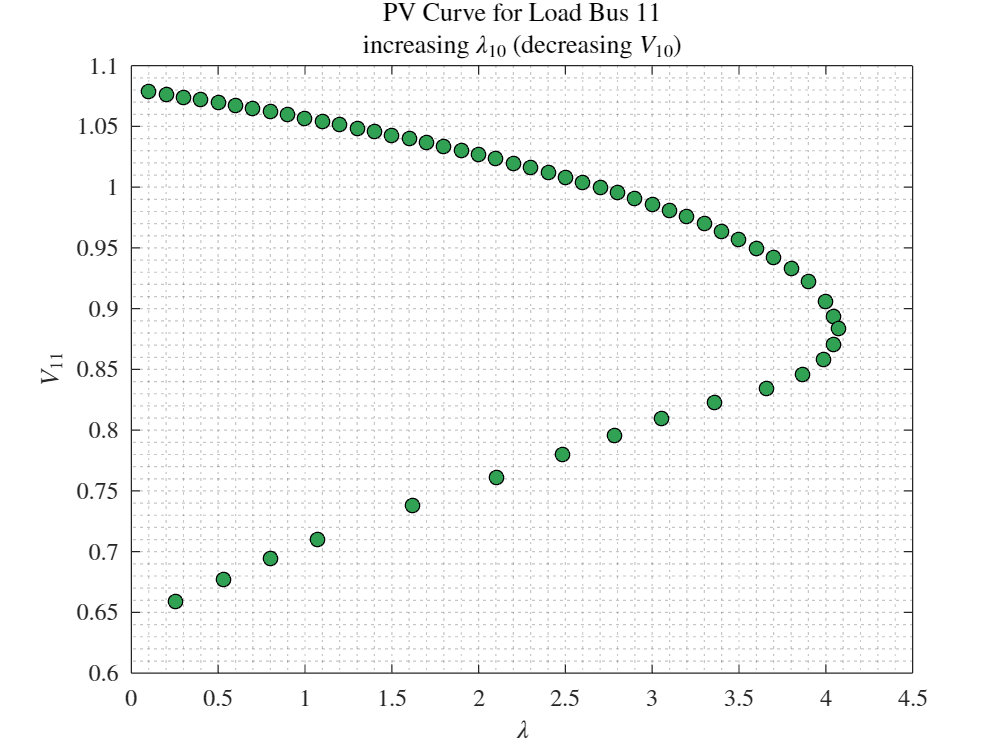

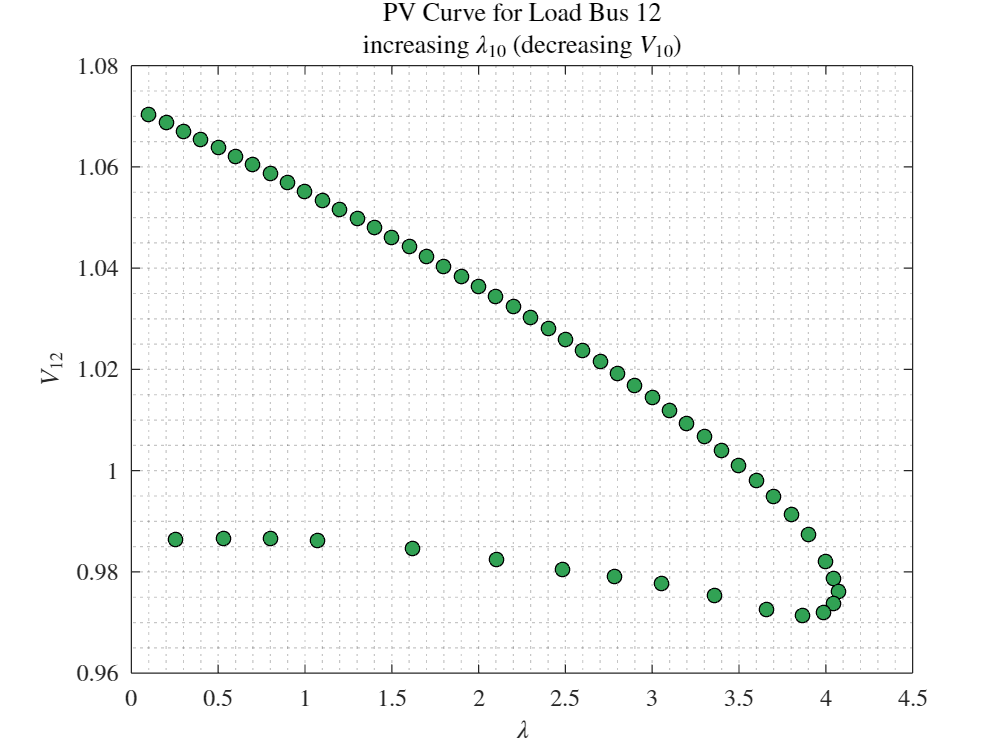

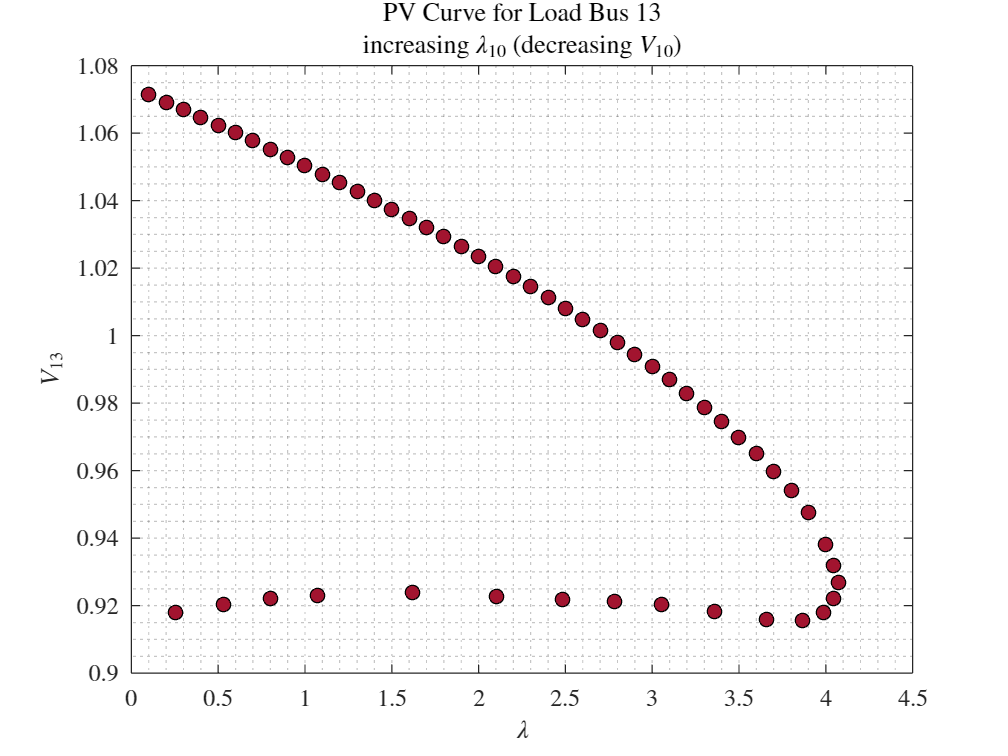

CPF_Progress_Table = 58×4 table
    Itr    lambda     V_10     sigma
    ___    ______    ______    _____

     1      0.1      1.0875     0.1 
     2      0.2      1.0838     0.1 
     3      0.3      1.0801     0.1 
     4      0.4      1.0762     0.1 
     5      0.5      1.0723     0.1 
     6      0.6      1.0682     0.1 
     7      0.7      1.0641     0.1 
     8      0.8      1.0598     0.1 
     9      0.9      1.0555     0.1 
    10        1       1.051     0.1 
    11      1.1      1.0465     0.1 
    12      1.2      1.0418     0.1 
    13      1.3       1.037     0.1 
    14      1.4       1.032     0.1 
    15      1.5      1.0269     0.1 
    16      1.6      1.0217     0.1 


[PSpecified, QSpecified, V, delta, ...
    listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
    listOfNonSlackBuses] = initializeVectors(busData, N, MVAb);

if useSparseDSA && ~doContinuationPowerFlow && ~includeOPFScenarios   
    doTheSparseThing(PSpecified, QSpecified, V, delta, nnzYBus, NYBus, busData); 
else
    if contains(systemName, 'caseThree')
        resultsFromCaseTwo = load("processedData\ieee11-caseTwoResults");
        resultsFromCaseTwo = resultsFromCaseTwo.resultTable;
        wiggle = 0.35; %minimum 0.35 value for good result
        V = V*(1-wiggle) + wiggle*resultsFromCaseTwo.V;
        delta = delta*(1-wiggle) + wiggle*resultsFromCaseTwo.delta;
    end
    
    if doContinuationPowerFlow && ~includeOPFScenarios
        desiredOutput = 'both';
        [V_CPF, delta_CPF, lambda_CPF, iter_CPF, sigma_CPF] =...
        continuationPowerFlow(busData, ybus, PSpecified, QSpecified, V, delta, BMatrix, E, ...
        nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, powerFlowMethod, desiredOutput, ...
        CPF_Bus, displayCPFResults, plotCPFPlots);
    else
        [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, N, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);
        resultTable = displayPowerFlowResults(N, P, Q, V, delta, displayResults);
        
        if contains(systemName, 'caseTwo') && strcmp(powerFlowMethod, 'NRPF')
            save("processedData\ieee11-caseTwoResults", "resultTable");
        end
    end
end

### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

if ~doContinuationPowerFlow
    plotPowerFlowResults(showPlots, useSparseDSA, V, busData, systemName, powerFlowMethod, delta);
end

### Economic Dispatch and Optimal Power Flow Calculations:

if includeOPFScenarios && strcmp(systemName, 'ieee14') && ~useSparseDSA
    runOPFScenarios(busData, P, Q, V, delta, N, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, powerFlowMethod, MVAb, showOPFFormulae, showOPFValues, printPowerFlowConvergenceMessages)
end
toc;

Elapsed time is 2.424569 seconds.


# Have a nice day! 

In case you encounter a Java Heap Memory error, delete the above gif, or go to `Preferences->General->Java Heap Memory` and increase the allocated size.